% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
disp('Baseline Decision Tree')
% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline Random Forest
disp('Baseline Random Forest')
% Train
rf_base = fitcensemble(X_train, y_train, 'Method', 'Bag');
% Evaluate
test_model(rf_base, X_test, y_test)

% 1c) Baseline KNN
disp('Baseline KNN')
% Train
knn_base = fitcknn(X_train, y_train, 'NumNeighbors', 2 ,'Standardize',1);
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% 1d) Baseline Logistic Regression
disp('Baseline Logistic Regression')

Baseline Logistic Regression


% Train
logit_base = fitglm(X_train, y_train, 'Distribution', 'binomial', 'link', 'logit')

logit_base = Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17
    Distribution = Binomial

Estimated Coefficients:
                   Estimate         SE           tStat         pValue  
                   _________    __________    ___________    __________

    (Intercept)      -78.142    1.5818e+07    -4.9402e-06             1
    x1              0.051534       0.17757        0.29021       0.77166
    x2              0.075019     0.0074522         10.067    7.7563e-24
    x3               0.50194       0.20203         2.4845      0.012974
    x4               0.20523       0.24335        0.84337       0.39902
    x5             -0.090916       0.30289  

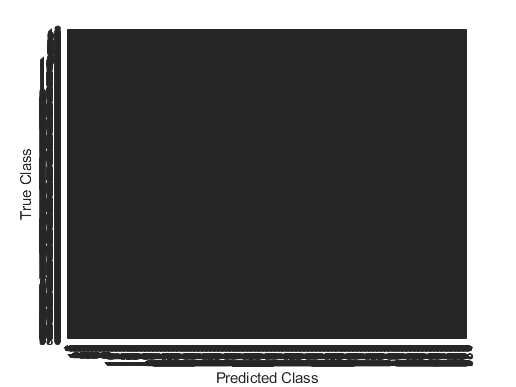

accuracy = 0

precision = 0

recall = NaN

specificity = 0

fb = 0

% Evaluate baseline knn
test_model(logit_base, X_test, y_test)

% ********** 2) Tuned Models **********

% 2a) Optimized Tree with CV
% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)
c= cvpartition(nrow,'KFold', 10)

% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1,20],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[1, 20],'Type','integer');
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical');
MinParentSize = optimizableVariable('MinParentSize', [1, 20], 'Type', 'integer');
CategoricalPredictors = optimizableVariable('CategoricalPredictors', [1, 17], 'Type', 'integer');

ParamsDT= [MaxNumSplit; MinLeaf; prior; MinParentSize; CategoricalPredictors];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_dt_cv(params,X_train,y_train, c), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'prior', 'uniform', 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeaf);

% Evaluate
test_model(dt_best, X_test, y_test)

% 2b) Optimized Random Forest with CV - TOOD: Implement!
% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)
c= cvpartition(nrow,'KFold', 10)

% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1,50],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[1, 50],'Type','integer');
ParamsRF= [MaxNumSplit; MinLeaf];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_rf_cv(params,X_train,y_train, c), ParamsRF,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitcensemble(X_train, y_train, 'prior', 'uniform', 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeaf);

% Evaluate
test_model(dt_best, X_test, y_test)

% 2c) Optimized KNN with CV
% Define vars and range
n = optimizableVariable('n',[1,20],'Type','integer');
dst = optimizableVariable('dst', {'chebychev','euclidean','minkowski'},'Type','categorical');
ParamsKNN= [n; dst];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_knn_cv(params,X_train,y_train, c), ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train,'NSMethod','exhaustive', 'Prior', 'uniform',...
            'NumNeighbors', z.n, 'Distance', char(z.dst));

% Evaluate
test_model(knn_best, X_test, y_test)

function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end

% Test model without CV folds
function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, ...
             'CategoricalPredictors', params.CategoricalPredictors, 'MinParentSize', params.MinParentSize, ...
            'prior', char(params.prior), 'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% rf function CV
function fb = fb_loss_rf_cv(params, X_train, y_train, cv_part)
        model = fitcensemble(X_train, y_train, 'CVPartition', cv_part, 'Method', 'Bag', 'exhaustive', 'prior', 'uniform',...
            'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end
% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, 'NSMethod', 'exhaustive', 'prior', 'uniform',...
            'NumNeighbors', params.n, 'Distance', char(params.dst));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end
% Fit
%fitglm(concatenatedPredictorsAndResponse, ...
%    'Distribution', 'binomial', ...
%    'link', 'logit')


%#ok<*ASGLU,*NOPRT> 